# **PID Controller Design and Analysis**

## Assignment 2

### **1 : Basic Plant Response Analysis**

#### a) Open-loop Analysis:

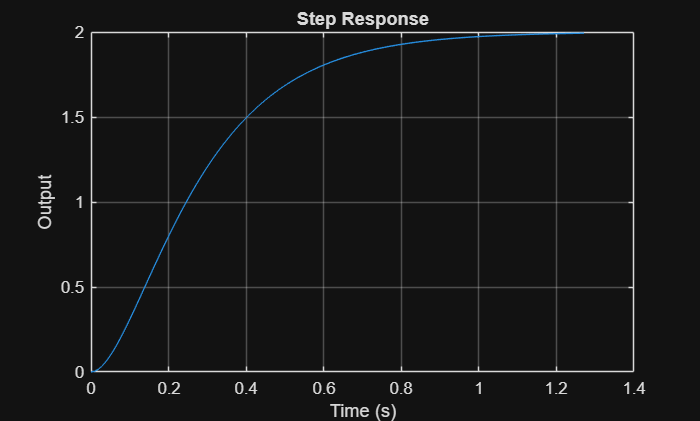

G=tf(100,[1,15,50]);
[y,t]=step(G);
plot(t, y);
grid on;
title('Step Response');
xlabel('Time (s)');
ylabel('Output');

info = stepinfo(G);
ess = 1 - y(end);
fprintf('Rise Time: %.3f s\n', info.RiseTime);

Rise Time: 0.518 s


fprintf('Settling Time:␣%.3f s\n', info.SettlingTime);

Settling Time:␣0.920 s


fprintf('Overshoot: %.2f%%\n', info.Overshoot);

Overshoot: 0.00%


fprintf('Peak: %.3f\n', info.Peak);

Peak: 1.998


fprintf('Steady State Error: %.3f\n', ess);

Steady State Error: -0.993


#### b) P Controller Design:

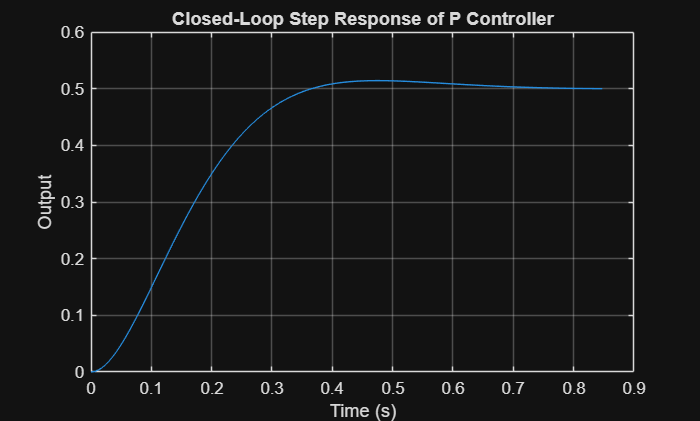

C = pid(0.5, 0, 0);
sys_cl = feedback(C*G, 1);
[y_cl, t_cl] = step(sys_cl);
plot(t_cl, y_cl);
title('Closed-Loop Step Response of P Controller');
xlabel('Time (s)');
ylabel('Output');
grid on;

info_cl = stepinfo(sys_cl);
ess_cl = 1 - y_cl(end);
fprintf('Rise Time: %.3f s\n', info_cl.RiseTime);

Rise Time: 0.229 s


fprintf('Settling Time:␣%.3f s\n', info_cl.SettlingTime);

Settling Time:␣0.574 s


fprintf('Overshoot: %.2f%%\n', info_cl.Overshoot);

Overshoot: 2.84%


fprintf('Peak: %.3f\n', info_cl.Peak);

Peak: 0.514


fprintf('Steady State Error: %.3f\n', ess_cl);

Steady State Error: 0.500


In a unity-feedback system with only P control, a nonzero steady‑state error exists because the controller output is proportional to the error, so some error must remain to generate the control effort needed to balance the load and plant dynamics.

#### c) PI Controller Design:

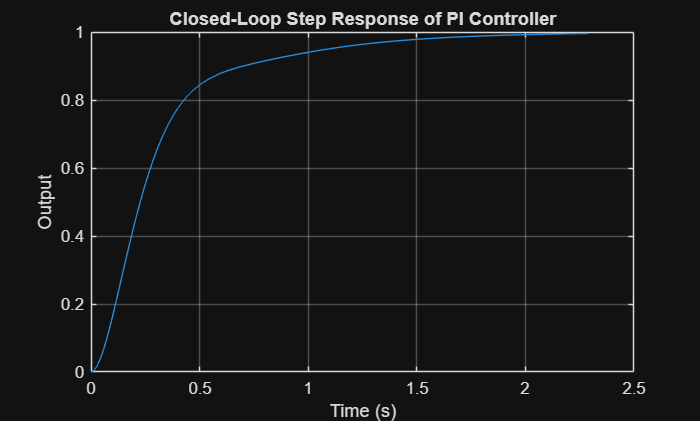

CI = pid(0.5, 1.5, 0);
sysI_cl = feedback(CI*G, 1);
[yI_cl, tI_cl] = step(sysI_cl);
plot(tI_cl, yI_cl);
title('Closed-Loop Step Response of PI Controller');
xlabel('Time (s)');
ylabel('Output');
grid on;

infoI_cl = stepinfo(sysI_cl);
essI_cl = 1 - yI_cl(end);
fprintf('Rise Time: %.3f s\n', infoI_cl.RiseTime);

Rise Time: 0.628 s


fprintf('Settling Time:␣%.3f s\n', infoI_cl.SettlingTime);

Settling Time:␣1.538 s


fprintf('Overshoot: %.2f%%\n', infoI_cl.Overshoot);

Overshoot: 0.00%


fprintf('Peak: %.3f\n', infoI_cl.Peak);

Peak: 0.998


fprintf('Steady State Error: %.3f\n', essI_cl);

Steady State Error: 0.004


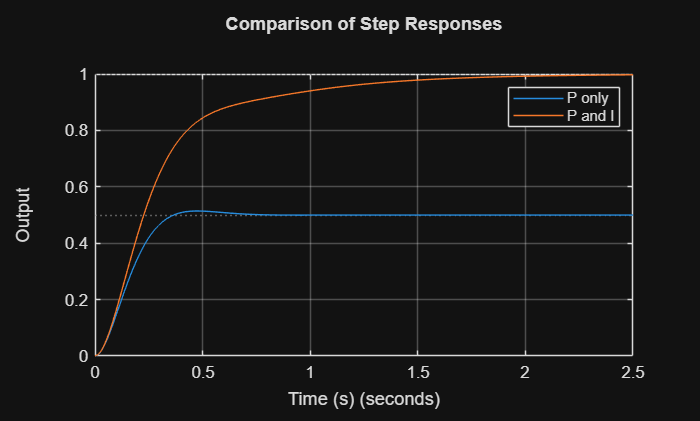

step(sys_cl, sysI_cl);
grid on;
legend('P only', 'P and I');
title('Comparison of Step Responses');
xlabel('Time (s)');
ylabel('Output');

Adding integral action makes the closed‑loop a TYPE-1 system, so for a step input the steady‑state error is driven essentially to zero because the integrator keeps changing the control signal as long as any error remains.

#### d) PID Controller Tuning:

pidTuner(G,'PID')
fprintf('Final PID Controller Gains:\n');

Final PID Controller Gains:


fprintf('Kp = %.4f\n', C_pid_tuned.Kp);

Kp = 1.3648


fprintf('Ki = %.4f\n', C_pid_tuned.Ki);

Ki = 6.4282


fprintf('Kd = %.4f\n', C_pid_tuned.Kd);

Kd = 0.0724


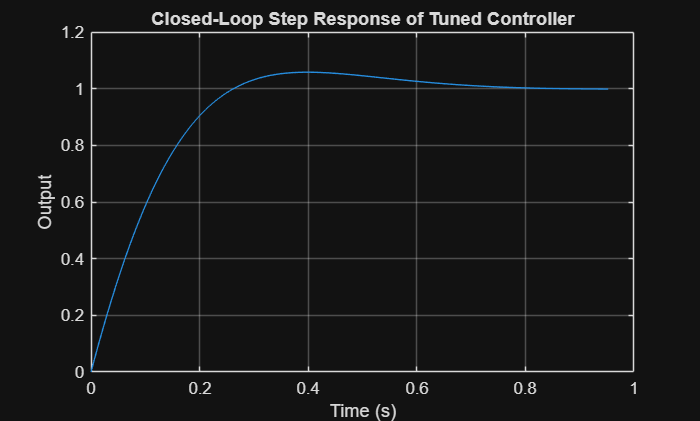

final = feedback(C_pid_tuned*G, 1);
[yf, t_f] = step(final);
plot(t_f, yf);
title('Closed-Loop Step Response of Tuned Controller');
xlabel('Time (s)');
ylabel('Output');
grid on;

infof = stepinfo(final);
essf = 1 - yf(end);
fprintf('Rise Time: %.3f s\n', infof.RiseTime);

Rise Time: 0.184 s


fprintf('Settling Time:␣%.3f s\n', infof.SettlingTime);

Settling Time:␣0.634 s


fprintf('Overshoot: %.2f%%\n', infof.Overshoot);

Overshoot: 5.81%


fprintf('Peak: %.3f\n', infof.Peak);

Peak: 1.058


fprintf('Steady State Error: %.3f\n', essf);

Steady State Error: 0.001


### 2 : Complex Input Tracking

#### a) Multi-Step Reference:

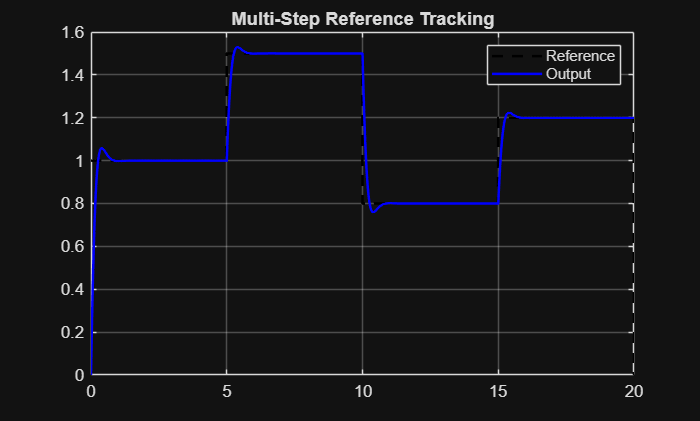

t = 0:0.01:20;
r = zeros(size(t));
for i = 1:length(t)
    if t(i) < 5
        r(i) = 1;
    elseif t(i) < 10
        r(i) = 1.5;
    elseif t(i) < 15
        r(i) = 0.8;
    elseif t(i)<20
        r(i) = 1.2; 
    end
end
[y2, t2] = lsim(final, r, t);
plot(t2,r,'k--',t2,y2,'b','LineWidth',1.5);
legend('Reference','Output');
title('Multi-Step Reference Tracking');
grid on;

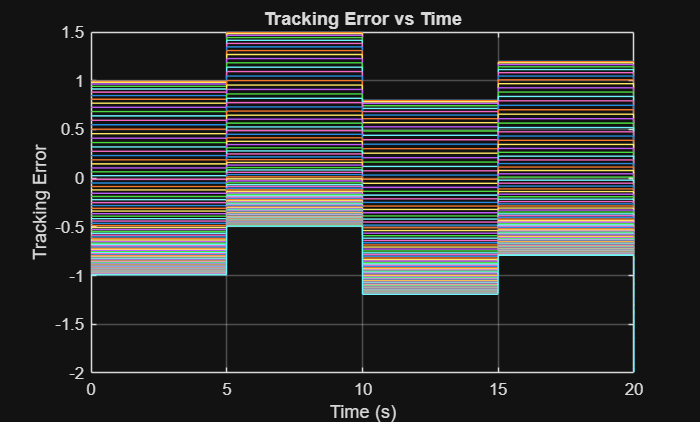


e = r - y;  

plot(t, e);
xlabel('Time (s)');
ylabel('Tracking Error');
title('Tracking Error vs Time');
grid on;

#### b) Ramp Input:

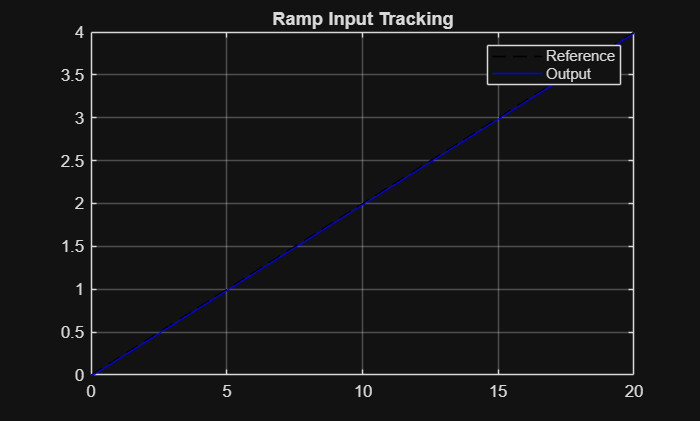

t = 0:0.01:20;
r = 0.2*t;
y = lsim(final,r,t);
e = r - y;
plot(t,r,'k--',t,y,'b');
legend('Reference','Output');
title('Ramp Input Tracking');
grid on;

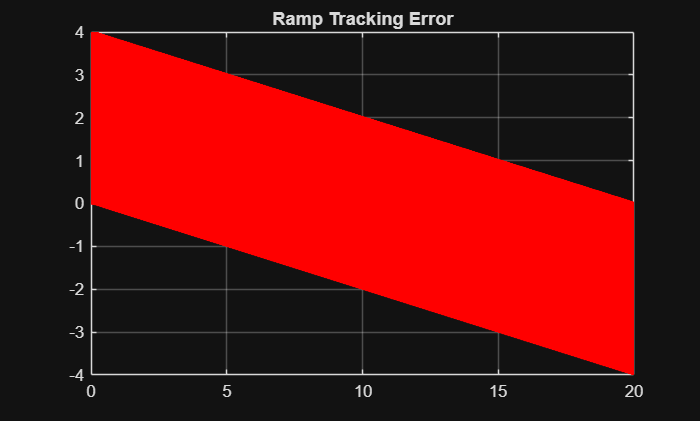

plot(t,e,'r','LineWidth',1.5);
title('Ramp Tracking Error');
grid on;

ess_ramp = mean(e(end-100:end))

ess_ramp = 0.1156

PID struggles with ramp tracking because it is a Type-1 system with only one integrator, which cannot eliminate steady-state error for a ramp input. A non-zero error is required to keep the integrator active, leading to constant lag. The derivative term does not increase system type and therefore cannot fix this limitation.

#### c) Sinusoidal Reference:

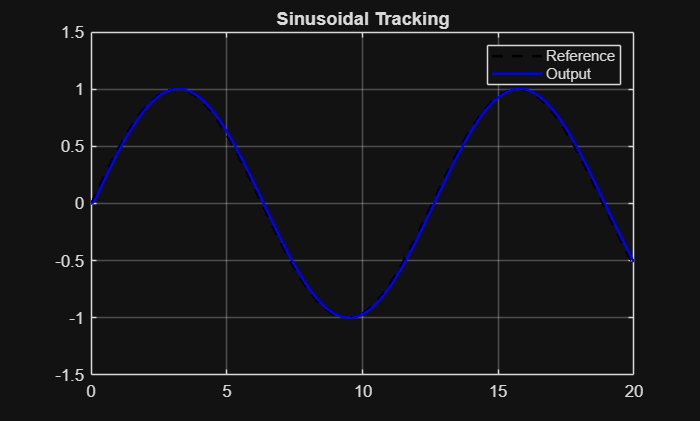

t = 0:0.01:20;
r = sin(0.5*t);

y = lsim(final,r,t);

figure;
plot(t,r,'k--',t,y,'b','LineWidth',1.5);
legend('Reference','Output');
title('Sinusoidal Tracking');
grid on;


[cor,lags] = xcorr(y,r);
[~,idx] = max(cor);
phase_lag = lags(idx)*0.01   

phase_lag = 0.0200

### 3 : Practical PID Implementation Challenges

#### a) Observing Integral Windup (Without Anti-Windup):

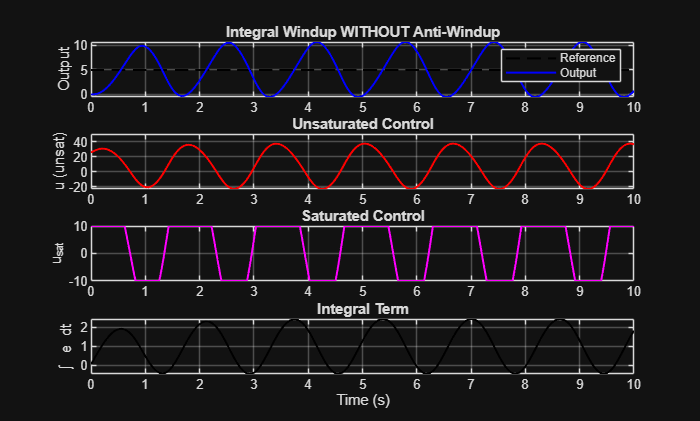

% Plant
G = tf(50,[1,8,25,20]);

% PID gains
Kp = 5; Ki = 8;

% Time
dt = 0.01;
t = 0:dt:10;

% Reference
r = 5*ones(size(t));

% Initialization
y = 0; dy = 0;ddy = 0;
e_int = 0;
u_hist = zeros(size(t));
y_hist = zeros(size(t));
u_sat_hist = zeros(size(t));
eint_hist = zeros(size(t));


for k = 1:length(t)
    e = r(k) - y;
    e_int = e_int + e*dt;          
   

    u = Kp*e + Ki*e_int;

    % Actuator saturation
    u_sat = max(min(u,10),-10);

    % Plant dynamics
    dddy = -8*ddy -25*dy -20*y + 50*u_sat;
    ddy  = ddy + dddy*dt;
    dy   = dy  + ddy*dt;
    y    = y   + dy*dt;

    u_hist(k) = u;
    y_hist(k) = y;
    u_sat_hist(k) = u_sat;
    eint_hist(k)  = e_int;
end

subplot(4,1,1)
plot(t,r,'k--',t,y_hist,'b','LineWidth',1.2)
grid on
title('Integral Windup WITHOUT Anti-Windup')
ylabel('Output')
legend('Reference','Output')

subplot(4,1,2)
plot(t,u_hist,'r','LineWidth',1.2)
grid on
ylabel('u (unsat)')
title('Unsaturated Control')

subplot(4,1,3)
plot(t,u_sat_hist,'m','LineWidth',1.2)
grid on
ylabel('u_{sat}')
title('Saturated Control')

subplot(4,1,4)
plot(t,eint_hist,'k','LineWidth',1.2)
grid on
xlabel('Time (s)')
ylabel('\int e dt')
title('Integral Term')

**1. When does saturation occur?     **Immediately after the step input at **t = 0 s**

**2. What happens to the integral term during saturation?   **The **integral term keeps growing**

**3. Effect on overshoot and settling time? **Large **overshoot and v**ery **slow settling**

#### b) Implementing Anti-Windup:

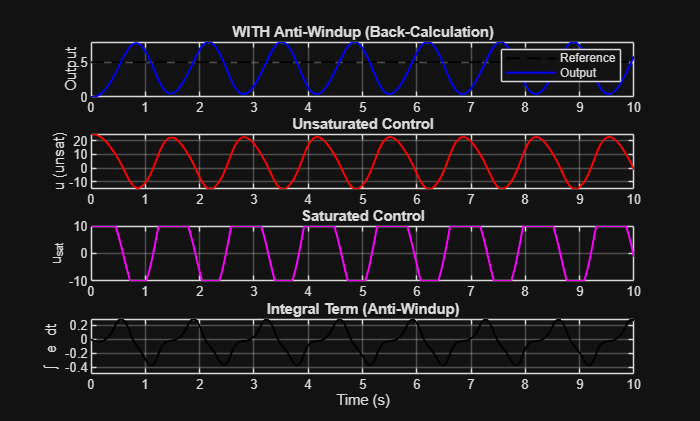

% Tracking gain
Kt = sqrt(Ki);     

% Time
dt = 0.01;
t = 0:dt:10;

% Reference
r = 5*ones(size(t));

% Initialization
y   = 0;
dy  = 0;
ddy = 0;
e_int = 0;

% Storage variables
y_aw        = zeros(size(t));
u_aw        = zeros(size(t));      
u_sat_aw    = zeros(size(t));      
eint_aw     = zeros(size(t));

for k = 1:length(t)
    e = r(k) - y;
    u = Kp*e + Ki*e_int;

    u_sat = max(min(u,10),-10);

    
    e_int = e_int + ( e + (1/Kt)*(u_sat - u) )*dt;
    

    % Plant dynamics 
    dddy = -8*ddy -25*dy -20*y + 50*u_sat;
    ddy  = ddy + dddy*dt;
    dy   = dy  + ddy*dt;
    y    = y   + dy*dt;

    
    y_aw(k)     = y;
    u_aw(k)     = u;
    u_sat_aw(k) = u_sat;
    eint_aw(k)  = e_int;
end
figure;

subplot(4,1,1)
plot(t,r,'k--',t,y_aw,'b','LineWidth',1.2)
grid on
title('WITH Anti-Windup (Back-Calculation)')
ylabel('Output')
legend('Reference','Output')

subplot(4,1,2)
plot(t,u_aw,'r','LineWidth',1.2)
grid on
ylabel('u (unsat)')
title('Unsaturated Control')

subplot(4,1,3)
plot(t,u_sat_aw,'m','LineWidth',1.2)
grid on
ylabel('u_{sat}')
title('Saturated Control')

subplot(4,1,4)
plot(t,eint_aw,'k','LineWidth',1.2)
grid on
xlabel('Time (s)')
ylabel('\int e dt')
title('Integral Term (Anti-Windup)')

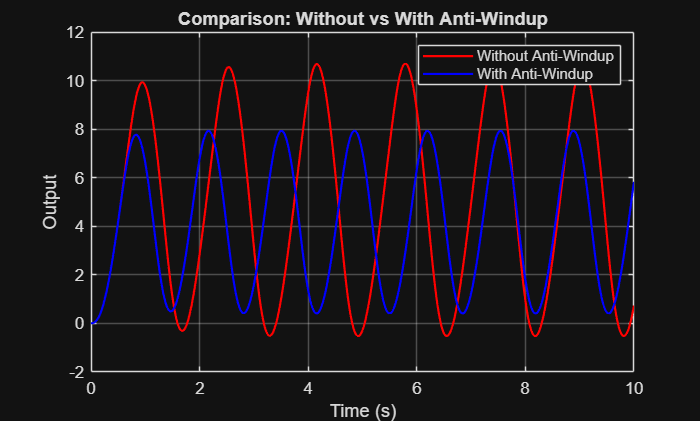


figure;
plot(t,y_hist,'r','LineWidth',1.3); hold on
plot(t,y_aw,'b','LineWidth',1.3)
grid on
xlabel('Time (s)')
ylabel('Output')
title('Comparison: Without vs With Anti-Windup')
legend('Without Anti-Windup','With Anti-Windup')

In anti-windup, the difference between the saturated and unsaturated control signals is fed back into the integrator. When saturation occurs, this feedback term cancels integral accumulation, preventing excessive windup. As a result, overshoot is reduced and settling time improves significantly.

#### c) Derivative Noise and Low-Pass Filtering:

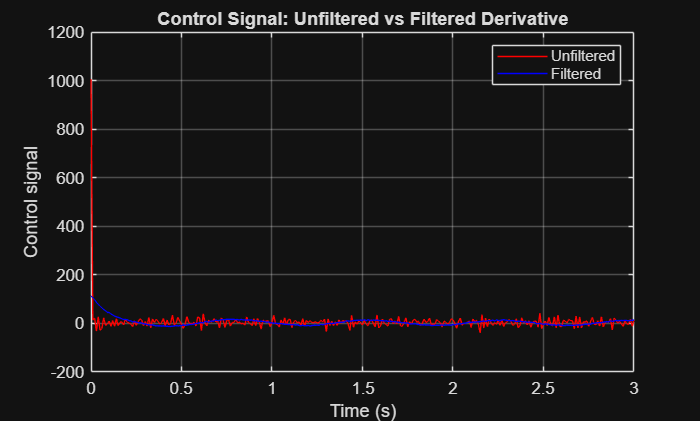

% PID gains
Kp = 5;
Ki = 8;
Kd = 2;

Kt = sqrt(Ki);     

% Time
dt = 0.01;
t  = 0:dt:10;

% Reference
r = 5*ones(size(t));

% Noise parameters
noise_amp = 0.05;

% Initialization
y   = 0;  dy = 0;  ddy = 0;
e_int = 0;
e_prev = 0;

% Storage
y_nf       = zeros(size(t));
u_nf       = zeros(size(t));
u_sat_nf   = zeros(size(t));

for k = 1:length(t)
    % Noisy measurement
    y_noisy = y + noise_amp*randn;
    % Error from noisy measurement
    e = r(k) - y_noisy;
    % Derivative (direct differentiation → noisy)
    u_d = Kd*(e - e_prev)/dt;
    % Unsaturated control
    u = Kp*e + Ki*e_int + u_d;
    % Saturation
    u_sat = max(min(u,10),-10);
    % Anti-windup (back-calculation)
    e_int = e_int + ( e + (1/Kt)*(u_sat - u) )*dt;
    % Plant dynamics
    dddy = -8*ddy -25*dy -20*y + 50*u_sat;
    ddy  = ddy + dddy*dt;
    dy   = dy  + ddy*dt;
    y    = y   + dy*dt;
    % Store
    y_nf(k)     = y;
    u_nf(k)     = u;
    u_sat_nf(k) = u_sat;
    e_prev = e;
end

% Reset states
y = 0; dy = 0; ddy = 0;
e_int = 0;
e_prev = 0;
ed_filt = 0;
% Filter parameters
tau = 0.1;
alpha = tau/(tau + dt);
% Storage
y_f       = zeros(size(t));
u_f       = zeros(size(t));
u_sat_f   = zeros(size(t));

for k = 1:length(t)
    % Noisy measurement
    y_noisy = y + noise_amp*randn;
    % Error
    e = r(k) - y_noisy;
    
    ed_filt = alpha*ed_filt + (1-alpha)*e;
    % Filtered derivative
    u_d = Kd*(ed_filt - e_prev)/dt;
    % Unsaturated control
    u = Kp*e + Ki*e_int + u_d;
    % Saturation
    u_sat = max(min(u,10),-10);
    % Anti-windup
    e_int = e_int + ( e + (1/Kt)*(u_sat - u) )*dt;
    % Plant dynamics
    dddy = -8*ddy -25*dy -20*y + 50*u_sat;
    ddy  = ddy + dddy*dt;
    dy   = dy  + ddy*dt;
    y    = y   + dy*dt;
    % Store
    y_f(k)     = y;
    u_f(k)     = u;
    u_sat_f(k) = u_sat;

    e_prev = ed_filt;
end

figure;
plot(t,u_nf,'r'); hold on
plot(t,u_f,'b')
grid on
xlabel('Time (s)')
ylabel('Control signal')
title('Control Signal: Unfiltered vs Filtered Derivative')
legend('Unfiltered','Filtered')
xlim([0 3])

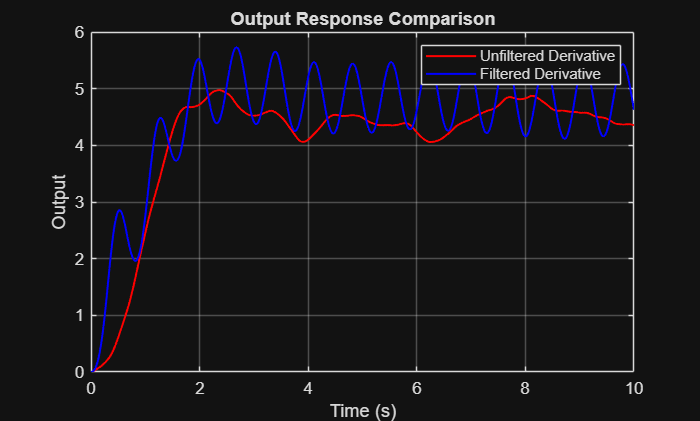


figure;
plot(t,y_nf,'r','LineWidth',1.2); hold on
plot(t,y_f,'b','LineWidth',1.2)
grid on
xlabel('Time (s)')
ylabel('Output')
title('Output Response Comparison')
legend('Unfiltered Derivative','Filtered Derivative')

By low-pass filtering first, we smooth out the noise before taking the derivative.This removes the rapid fluctuations that the derivative would otherwise amplify.Because of this, the controller still gets the useful damping effect of the derivative

#### d) Complex Trajectory Tracking:

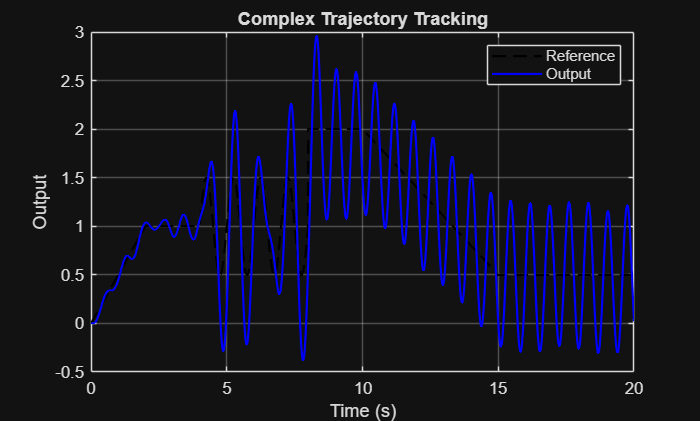

% Time
dt = 0.01;
t  = 0:dt:20;
N  = length(t);

% Noise
noise_amp = 0.05;

% Filter parameters
tau = 0.1;
alpha = tau/(tau + dt);

% Initialization
y   = 0; dy = 0; ddy = 0;
e_int = 0;
e_prev = 0;
ed_filt = 0;

% Storage
r_hist   = zeros(1,N);
y_hist   = zeros(1,N);
e_hist   = zeros(1,N);
u_hist   = zeros(1,N);
u_sat_hist = zeros(1,N);

for k = 1:N
    tk = t(k);

    if tk < 2
        r_hist(k) = 0.5*tk;                      
    elseif tk < 4
        r_hist(k) = 1;                          
    elseif tk < 8
        r_hist(k) = 1 + 0.5*sin(2*pi*(tk-4));    
    elseif tk < 10
        r_hist(k) = 2;                         
    elseif tk < 15
        r_hist(k) = 2 - 0.3*(tk-10);              
    else
        r_hist(k) = 0.5;                 
    end
end

for k = 1:N

    % Noisy measurement
    y_noisy = y + noise_amp*randn;
    % Tracking error
    e = r_hist(k) - y_noisy;
    % Filter error before differentiation
    ed_filt = alpha*ed_filt + (1-alpha)*e;
    % Derivative term
    u_d = Kd*(ed_filt - e_prev)/dt;
    % Unsaturated control
    u = Kp*e + Ki*e_int + u_d;
    % Saturation
    u_sat = max(min(u,10),-10);
    % Anti-windup (back-calculation)
    e_int = e_int + ( e + (1/Kt)*(u_sat - u) )*dt;
    % Plant dynamics (3rd order)
    dddy = -8*ddy -25*dy -20*y + 50*u_sat;
    ddy  = ddy + dddy*dt;
    dy   = dy  + ddy*dt;
    y    = y   + dy*dt;
    % Store
    y_hist(k)     = y;
    e_hist(k)     = e;
    u_hist(k)     = u;
    u_sat_hist(k) = u_sat;
    e_prev = ed_filt;
end
figure;
plot(t,r_hist,'k--','LineWidth',1.3); hold on
plot(t,y_hist,'b','LineWidth',1.3)
grid on
xlabel('Time (s)')
ylabel('Output')
title('Complex Trajectory Tracking')
legend('Reference','Output')

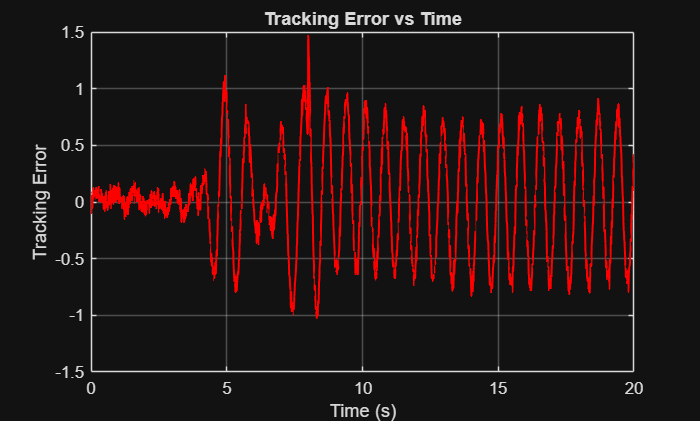

figure;
plot(t,e_hist,'r','LineWidth',1.2)
grid on
xlabel('Time (s)')
ylabel('Tracking Error')
title('Tracking Error vs Time')

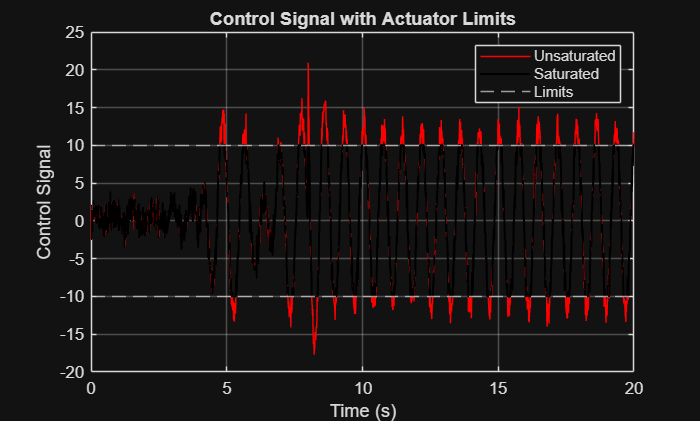

figure;
plot(t,u_hist,'r'); hold on
plot(t,u_sat_hist,'k','LineWidth',1.2)
yline(10,'--'); yline(-10,'--')
grid on
xlabel('Time (s)')
ylabel('Control Signal')
title('Control Signal with Actuator Limits')
legend('Unsaturated','Saturated','Limits')

**Ramp:**The integral part slowly builds up to remove the error, so the output follows the ramp smoothly without staying behind.

**Step :**When the reference suddenly changes, the motor hits its voltage limit.Anti-windup stops the controller from “over-charging” the integral part, so the output does not overshoot too much.

**Sinusoidal :**The derivative helps the system react faster, but noise can make it jumpy.Filtering the derivative smooths this out, so the output follows the wave without shaking.

**Actuator limits:**The control signal never goes beyond ±10 V, so the motor is always working within safe limits.